# **两次优化**

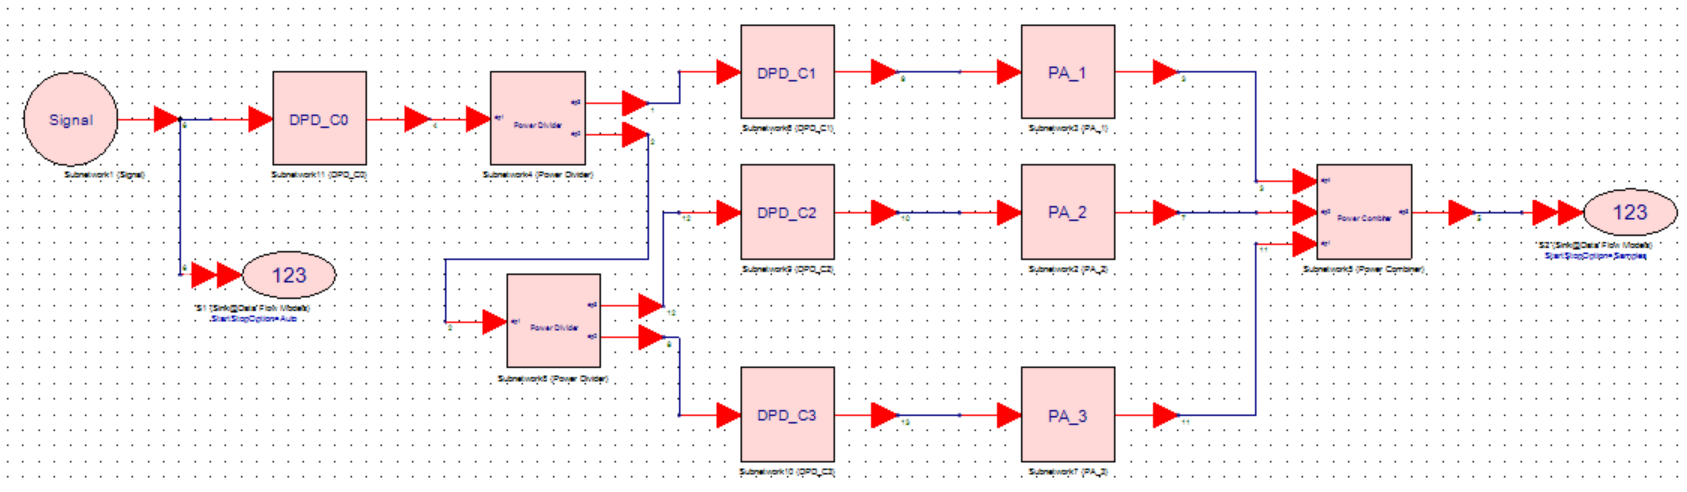

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Model C Train----------------------------

## 读取数据

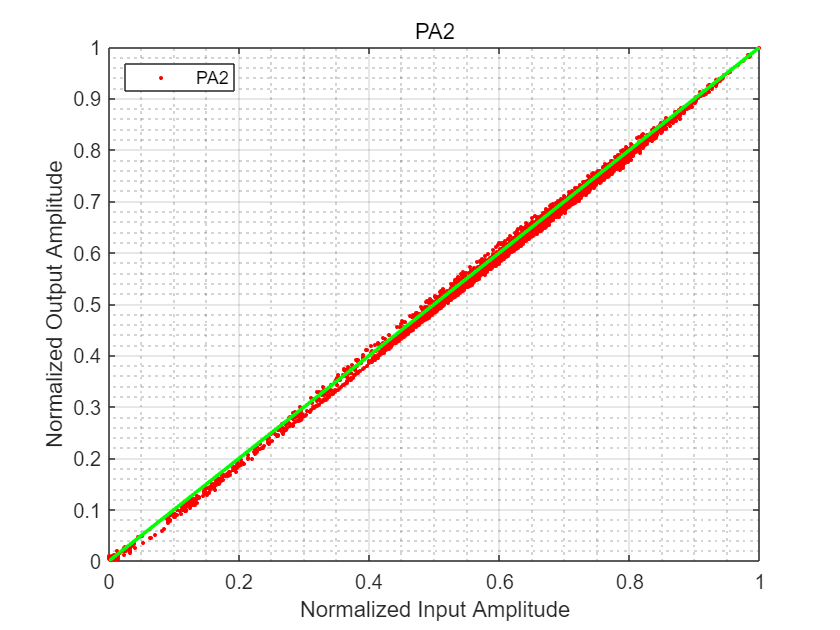

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
PA1_output = Data_matrix(:,3) + 1i * Data_matrix(:,4); 
PA2_output = Data_matrix(:,5) + 1i * Data_matrix(:,6); 
PA3_output = Data_matrix(:,7) + 1i * Data_matrix(:,8); 
PA1_input = 0.5*Sys_input;
PA2_input = 0.25*Sys_input;
PA3_input = 0.25*Sys_input;
% 参数需要保持一致
M = 5; 
Plot_AM(PA2_input,PA2_output,'PA2','PA2');

## 【训练PA3】

% % 模型训练
% path = 'Method_C\PA3\FNN.mat';
% model=Train_FNN(M,PA3_input,PA3_output,[8,8]);
% save(path, 'model');
% % 模型精度
% [model_input,model_output] = pre_train(M,PA3_input,PA3_output,dim);
% data = load(path);
% DPD_output_m = sim(data.model,model_input);
% DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
% nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
% fprintf('模型的拟合精度NMSE为 %f dB\n', nmse);

## 【训练PA2】

% % 模型训练
% path = 'Method_C\PA2\FNN.mat';
% model=Train_FNN(M,PA2_input,PA2_output,[8,8]);
% save(path, 'model');
% % 模型精度
% [model_input,model_output] = pre_train(M,PA2_input,PA2_output,dim);
% data = load(path);
% DPD_output_m = sim(data.model,model_input);
% DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
% nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
% fprintf('模型的拟合精度NMSE为 %f dB\n', nmse);

## 【训练PA1】

path = 'Method_C\PA1\FNN.mat';
% 模型训练
model=Train_FNN(M,PA1_input,PA1_output,[64,32,16,8]);
save(path, 'model');
% 模型精度
[model_input,model_output] = pre_train(M,PA1_input,PA1_output,dim);
data = load(path);
DPD_output_m = sim(data.model,model_input);
DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
fprintf('模型的拟合精度NMSE为 %f dB\n', nmse);

## 第一次迭代

% 系统仿真
[A1_input,A23] = Power_Divider(Sys_input);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD1 = DPD_sim(A1_input,M,'Method_C\PA1\FNN.mat');
A1_output = PA_1(A1_input_DPD1);
A2_input_DPD = DPD_sim(A2_input,M,'Method_C\PA2\FNN.mat');
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD_sim(A3_input,M,'Method_C\PA3\FNN.mat');
A3_output = PA_3(A3_input_DPD);
Sys_output_middle = Power_Combiner(A1_output,A2_output,A3_output);
% 中间评估
nmse_middle = NMSE_dB(Sys_input,Sys_output_middle)

nmse_middle = -39.2187

nmse_1 = NMSE_dB(A1_input,A1_output)

nmse_1 = -33.6773

nmse_2 = NMSE_dB(A2_input,A2_output)

nmse_2 = -46.2970

nmse_3 = NMSE_dB(A3_input,A3_output)

nmse_3 = -49.1794

## 【训练】整体优化

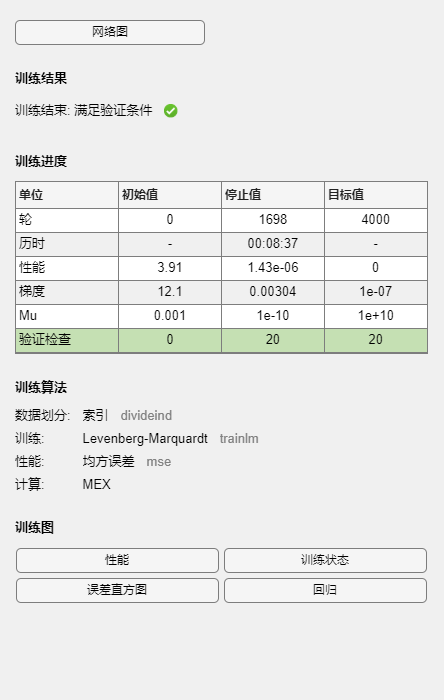

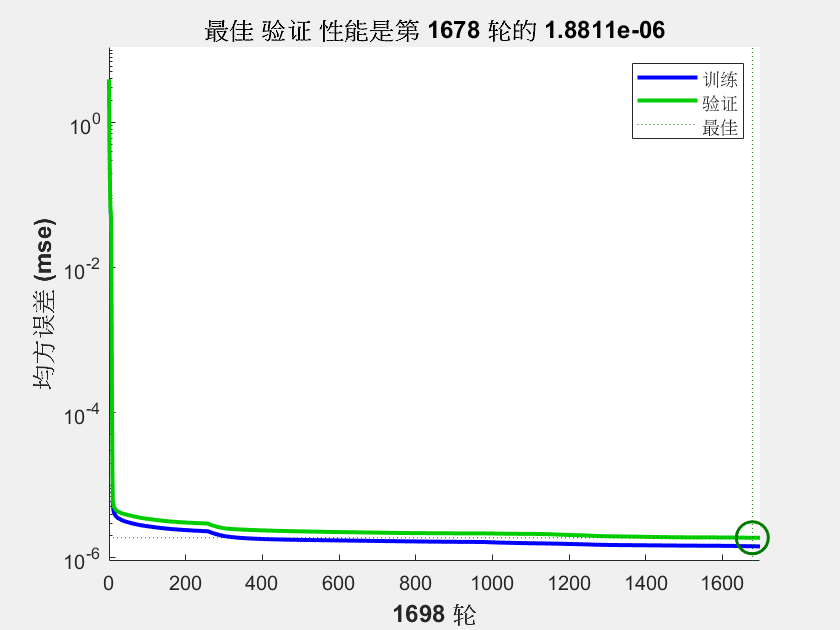

% 模型训练
model=Train_FNN(M,Sys_input,Sys_output_middle,[32,16,8]);

save('Method_C\Whole\FNN.mat', 'model');

## Model Test

% 系统仿真
Sys_input_DPD=DPD_sim(Sys_input,M,'Method_C\Whole\FNN.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD1 = DPD_sim(A1_input,M,'Method_C\PA1\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD1);
A2_input_DPD = DPD_sim(A2_input,M,'Method_C\PA2\FNN.mat'); % DPD
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD_sim(A3_input,M,'Method_C\PA3\FNN.mat'); % DPD
A3_output = PA_3(A3_input_DPD);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
nmse = NMSE_dB(Sys_input,Sys_output);
nmse_1 = NMSE_dB(A1_input,A1_output)

nmse_1 = -39.7129

nmse_2 = NMSE_dB(A2_input,A2_output)

nmse_2 = -45.4303

nmse_3 = NMSE_dB(A3_input,A3_output)

nmse_3 = -48.4961

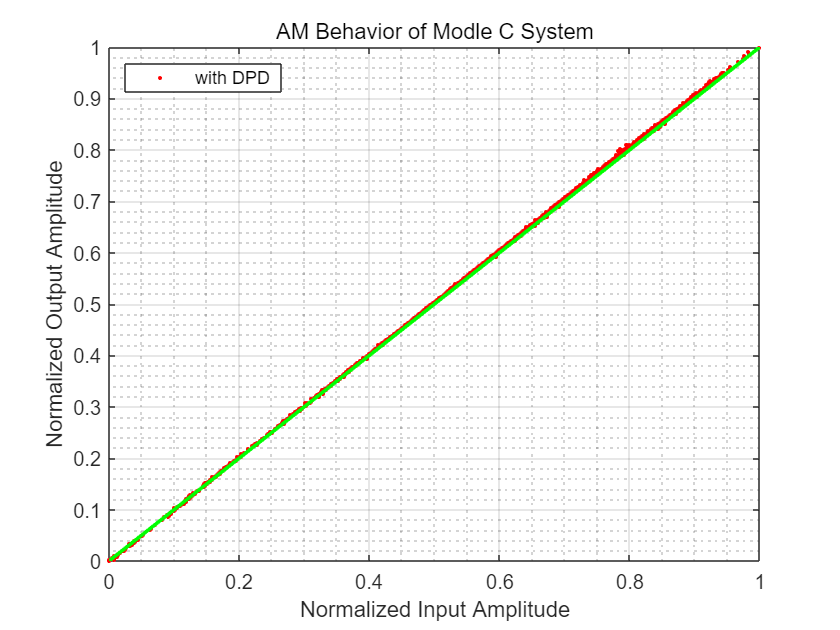

Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD');

fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse);

使用Model C，系统的NMSE仿真结果为 -43.179642 dB


## -----------------------------Model C Valid----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
% 参数需要保持一致
M = 5;

## Model Test

% 系统仿真
Sys_input_DPD=DPD_sim(Sys_input,M,'Method_C\Whole\FNN.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD1 = DPD_sim(A1_input,M,'Method_C\PA1\FNN.mat'); % DPD
% A1_input_DPD2 = DPD_sim(A1_input_DPD1,M,'Method_C\PA1\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD1);
A2_input_DPD = DPD_sim(A2_input,M,'Method_C\PA2\FNN.mat'); % DPD
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD_sim(A3_input,M,'Method_C\PA3\FNN.mat'); % DPD
A3_output = PA_3(A3_input_DPD);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA和DPD的延时，所以少算（4+2M）个值
Sys_input = Sys_input(5+M*2:end);
Sys_output = Sys_output(5+M*2:end);
% 性能评估
Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD_predict');
nmse_sim= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse_sim);